clc;clear;close all;

## -------------------------------读取点云---------------------------------

warning off
% load('ShiCe.mat')
% points = [points(3,:);points(1,:);points(2,:)];
% P3 = [P3(3),P3(1),P3(2)];
% P4 = [P4(3),P4(1),P4(2)];
% 
% 
% load('data.mat')
% points = [data(:,1)';data(:,2)';data(:,3)';];



azimuth = 5.135899059569828;
elevation = 1.57897350050879;

r = 1;
x0 = r.*cos(azimuth).*cos(elevation);
y0 = r.*cos(azimuth).*sin(elevation);
z0 = r.*sin(azimuth);
Tao = [x0,y0,z0]

Tao =    -0.0034    0.4109   -0.9117


P3 = [0.698625642652000,1.04004032326448,-0.573794783259771]+Tao;
P4 = [0.710558671267955,-0.419236813348415,-0.777745273229581]-Tao;


num = 8;
laynum = 5;

% 测试 生成 一个截面 测点
Point_out = generate_unit_circle_with_normal_vector2(azimuth,elevation,num,laynum,P3,P4);


% % 测试 生成 所有测点
% Point_tset = Generate_multi_layered_measurement_points(Point_out,num,laynum,P3,P4);


% 测试 测点的拟合
tic
[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Point_out,P3,P4)

Mcenter =     0.0002   -0.0044   -0.0020


MTaon =     0.0037   -0.4168    0.9090


Mradial = 1.0000

Err_every =    -0.0035
   -0.0052
   -0.0045
   -0.0019
    0.0015
    0.0043
    0.0052
    0.0038
   -0.0018
   -0.0026


Bottom_round_center1 =    -0.0069    0.8095   -1.7768


Bottom_round_center2 =     0.0019   -0.2004    0.4256


toc

历时 3.257820 秒。


figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
% quiver3(0,0,0,5*x0,5*y0,5*z0)
scatter3(Point_out(1,:),Point_out(2,:),Point_out(3,:),5,"filled");
scatter3([P3(1),P4(1)],[P3(2),P4(2)],[P3(3),P4(3)],10,"filled");

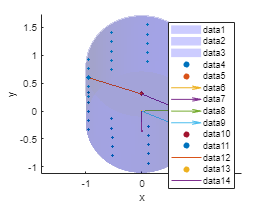

% 计算45（phi）面的法向量D

A = [0,0,1];
B = MTaon;    %%%%%%%%%%%%%%%%% 输入角度  法向量 %%%%%%%%%%%%
C = cross(A,B);
C = C./norm(C);
phi = pi/4;        %%%%%%%%%%%%%%%%% 输入角度  声道角 %%%%%%%%%%%%
D = B+tan(phi)*C;
D = D./norm(D);
E = cross(cross(B,C),D);
E = E./norm(E);



quiver3(0,0,0,A(1),A(2),A(3))
quiver3(0,0,0,B(1),B(2),B(3))
quiver3(0,0,0,C(1),C(2),C(3))
quiver3(0,0,0,D(1),D(2),D(3))
legend



% 随机抽一个中间面的点
testP = Point_out(:,20);   %%%%%%%%%%%%%%%%% 输入角度  中间面的一个点 %%%%%%%%%%%%


% 圆心点
[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(testP,Mcenter,Mcenter+MTaon);

scatter3(xN1,yN1,zN1,20,'filled')
scatter3(testP(1),testP(2),testP(3),20,'filled')
plot3([xN1,testP(1)],[yN1,testP(2)],[zN1,testP(3)])


% 面法向量第二个点（与圆心点构成45（phi）面的法向量）
Tao2 = [xN1,yN1,zN1] + D;
scatter3(Tao2(1),Tao2(2),Tao2(3),20,'filled')
plot3([xN1,Tao2(1)],[yN1,Tao2(2)],[zN1,Tao2(3)])



% 起始点 （测点半圆的中点）
QiShi = [xN1,yN1,zN1] + E;


% 构建旋转矩阵

theta = atan2(norm(cross([0, 0, 1], MTaon)), dot([0, 0, 1], MTaon));
v = cross([0, 0, 1],MTaon) / norm(cross([0, 0, 1], MTaon));
rot1 = myvrrotvec2mat([v, theta]);


% 选择旋转点集合
Prot(1:3,1) = [xN1;yN1;zN1]; % 圆心点
Prot(1:3,2) = Tao2';  % 面法向量第二个点
Prot(1:3,3) = Bottom_round_center1'; % 圆底面点1
Prot(1:3,4) = Bottom_round_center2'; % 圆底面点2
Prot(1:3,5) = QiShi'; % 起始点 （测点半圆的中点）

% 旋转至【0，0，1】的点集合
P2D = Prot'*rot1;
% plotcylinder(P2D(3,:),P2D(4,:),'b',Mradial,0.2)

P2DT = P2D - repmat([P2D(1,1),P2D(1,2),0],size(P2D,1),1);

% 旋转、平移后 法向量
Tao3 = P2DT(2,:) - P2DT(1,:);

% 法平面参数 aa,bb,cc,dd 过点 P2DT(1,:) ，法向量Tao3
aa = Tao3(1)

aa = 0.7071

bb = Tao3(2)

bb = 0.0062

cc = Tao3(3)

cc = 0.7071

dd = -(aa*P2DT(1,1)+bb*P2DT(1,2)+cc*P2DT(1,3))

dd = 0.5258

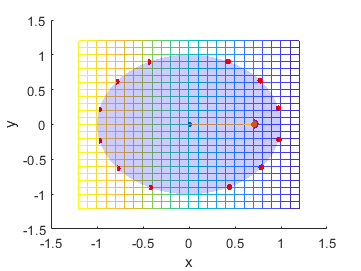


figure
hold on
plotcylinder(P2DT(3,:),P2DT(4,:),'b',Mradial,0.2)
scatter3(P2DT(1,1),P2DT(1,2),P2DT(1,3),20,'filled')
scatter3(aa,bb,cc,20,'filled')
plot3([P2DT(1,1),aa],[P2DT(1,2),bb],[P2DT(1,3),cc])
scatter3(P2DT(5,1),P2DT(5,2),P2DT(5,3),50,'filled')

x = -1.2 : 0.1 : 1.2;
y = -1.2 : 0.1 : 1.2;
[X, Y] = meshgrid(x, y);
Z = -(aa*X+bb*Y+dd)./cc;
mesh(X, Y, Z);
xlabel('x')
ylabel('y')
zlabel('z')

% 起始角度
Ang1 = atan(P2DT(5,2)/P2DT(5,1));
A1x = cos(Ang1);
A1y = sin(Ang1);
A1z = -(dd+aa*A1x+bb*A1y)/cc;


numShengLu = 6; %%%%%%%%%%%%%%%%% 输入角度 声路数 %%%%%%%%%%%%

% 根据声路数画出测点
switch numShengLu
    case 1
        PointTable2DT_A = [A1x,A1y,A1z];
%         PointTable2DT_A(2:10,:) = [];
    case 2
        Ang2 = Ang1 - pi/6;
        Ang3 = Ang1 + pi/6;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z];
%         PointTable2DT_A(3:10,:) = [];
    case 3
        Ang2 = Ang1 - pi/4;
        Ang3 = Ang1 + pi/4;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A1x,A1y,A1z;A3x,A3y,A3z];
%         PointTable2DT_A(4:10,:) = [];
    case 4
        Ang2 = Ang1-0.3*pi;
        Ang3 = Ang1-0.1*pi;
        Ang4 = Ang1+0.1*pi;
        Ang5 = Ang1+0.3*pi;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z;A4x,A4y,A4z;A5x,A5y,A5z];
%         PointTable2DT_A(5:10,:) = [];
    case 5
        Ang2 = Ang1-1/3*pi;
        Ang3 = Ang1-1/6*pi;
        Ang4 = Ang1+1/6*pi;
        Ang5 = Ang1+1/3*pi;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z; A3x,A3y,A3z; A1x,A1y,A1z; A4x,A4y,A4z; A5x,A5y,A5z];
%         PointTable2DT_A(6:10,:) = [];
    case 6
        temp = 1/7*pi;
        Ang2 = Ang1-1/2*pi+temp;
        Ang3 = Ang1-1/2*pi+2*temp;
        Ang4 = Ang1-1/2*pi+3*temp;
        Ang5 = Ang1-1/2*pi+4*temp;
        Ang6 = Ang1-1/2*pi+5*temp;
        Ang7 = Ang1-1/2*pi+6*temp;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        [A6x,A6y,A6z] = angle2point(Ang6,aa,bb,cc,dd,Mradial);
        [A7x,A7y,A7z] = angle2point(Ang7,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z;A4x,A4y,A4z;A5x,A5y,A5z;A6x,A6y,A6z;A7x,A7y,A7z];
%         PointTable2DT_A(7:10,:) = [];
    case 7
        temp = 1/8*pi;
        Ang2 = Ang1-1/2*pi+temp;
        Ang3 = Ang1-1/2*pi+2*temp;
        Ang4 = Ang1-1/2*pi+3*temp;
        Ang5 = Ang1-1/2*pi+4*temp;
        Ang6 = Ang1-1/2*pi+5*temp;
        Ang7 = Ang1-1/2*pi+6*temp;
        Ang8 = Ang1-1/2*pi+7*temp;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        [A6x,A6y,A6z] = angle2point(Ang6,aa,bb,cc,dd,Mradial);
        [A7x,A7y,A7z] = angle2point(Ang7,aa,bb,cc,dd,Mradial);
        [A8x,A8y,A8z] = angle2point(Ang8,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z;A4x,A4y,A4z;A5x,A5y,A5z;A6x,A6y,A6z;A7x,A7y,A7z;A8x,A8y,A8z];
%         PointTable2DT_A(8:10,:) = [];
    case 8
        temp = 1/9*pi;
        Ang2 = Ang1-1/2*pi+temp;
        Ang3 = Ang1-1/2*pi+2*temp;
        Ang4 = Ang1-1/2*pi+3*temp;
        Ang5 = Ang1-1/2*pi+4*temp;
        Ang6 = Ang1-1/2*pi+5*temp;
        Ang7 = Ang1-1/2*pi+6*temp;
        Ang8 = Ang1-1/2*pi+7*temp;
        Ang9 = Ang1-1/2*pi+8*temp;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        [A6x,A6y,A6z] = angle2point(Ang6,aa,bb,cc,dd,Mradial);
        [A7x,A7y,A7z] = angle2point(Ang7,aa,bb,cc,dd,Mradial);
        [A8x,A8y,A8z] = angle2point(Ang8,aa,bb,cc,dd,Mradial);
        [A9x,A9y,A9z] = angle2point(Ang9,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z;A4x,A4y,A4z;A5x,A5y,A5z;A6x,A6y,A6z;A7x,A7y,A7z;A8x,A8y,A8z;A9x,A9y,A9z];
%         PointTable2DT_A(9:10,:) = [];
    case 9
        temp = 1/10*pi;
        Ang2 = Ang1-1/2*pi+temp;
        Ang3 = Ang1-1/2*pi+2*temp;
        Ang4 = Ang1-1/2*pi+3*temp;
        Ang5 = Ang1-1/2*pi+4*temp;
        Ang6 = Ang1-1/2*pi+5*temp;
        Ang7 = Ang1-1/2*pi+6*temp;
        Ang8 = Ang1-1/2*pi+7*temp;
        Ang9 = Ang1-1/2*pi+8*temp;
        Ang10 = Ang1-1/2*pi+9*temp;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        [A6x,A6y,A6z] = angle2point(Ang6,aa,bb,cc,dd,Mradial);
        [A7x,A7y,A7z] = angle2point(Ang7,aa,bb,cc,dd,Mradial);
        [A8x,A8y,A8z] = angle2point(Ang8,aa,bb,cc,dd,Mradial);
        [A9x,A9y,A9z] = angle2point(Ang9,aa,bb,cc,dd,Mradial);
        [A10x,A10y,A10z] = angle2point(Ang10,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z;A4x,A4y,A4z;A5x,A5y,A5z;A6x,A6y,A6z;A7x,A7y,A7z;A8x,A8y,A8z;A9x,A9y,A9z;A10x,A10y,A10z];
%         PointTable2DT_A(10,:) = [];
    case 10
         temp = 1/10*pi;
        Ang2 = Ang1-1/2*pi+temp;
        Ang3 = Ang1-1/2*pi+2*temp;
        Ang4 = Ang1-1/2*pi+3*temp;
        Ang5 = Ang1-1/2*pi+4*temp;
        Ang6 = Ang1-1/2*pi+5*temp;
        Ang7 = Ang1-1/2*pi+6*temp;
        Ang8 = Ang1-1/2*pi+7*temp;
        Ang9 = Ang1-1/2*pi+8*temp;
        Ang10 = Ang1-1/2*pi+9*temp;
        Ang11 = Ang1-1/2*pi+10*temp;
        [A2x,A2y,A2z] = angle2point(Ang2,aa,bb,cc,dd,Mradial);
        [A3x,A3y,A3z] = angle2point(Ang3,aa,bb,cc,dd,Mradial);
        [A4x,A4y,A4z] = angle2point(Ang4,aa,bb,cc,dd,Mradial);
        [A5x,A5y,A5z] = angle2point(Ang5,aa,bb,cc,dd,Mradial);
        [A6x,A6y,A6z] = angle2point(Ang6,aa,bb,cc,dd,Mradial);
        [A7x,A7y,A7z] = angle2point(Ang7,aa,bb,cc,dd,Mradial);
        [A8x,A8y,A8z] = angle2point(Ang8,aa,bb,cc,dd,Mradial);
        [A9x,A9y,A9z] = angle2point(Ang9,aa,bb,cc,dd,Mradial);
        [A10x,A10y,A10z] = angle2point(Ang10,aa,bb,cc,dd,Mradial);
        [A11x,A11y,A11z] = angle2point(Ang11,aa,bb,cc,dd,Mradial);
        PointTable2DT_A = [A2x,A2y,A2z;A3x,A3y,A3z;A4x,A4y,A4z;A5x,A5y,A5z;A6x,A6y,A6z;A7x,A7y,A7z;A8x,A8y,A8z;A9x,A9y,A9z;A10x,A10y,A10z;A11x,A11y,A11z];
    otherwise
        disp('other value')
end



Xcen2D = P2DT(1,1);
Ycen2D = P2DT(1,2);
Zcen2D = P2DT(1,3);
tempx = 2*Xcen2D - PointTable2DT_A(:,1);
tempy = 2*Ycen2D - PointTable2DT_A(:,2);
tempz = 2*Zcen2D - PointTable2DT_A(:,3);
PointTable2DT_A = [PointTable2DT_A;[tempx,tempy,tempz]];

scatter3(PointTable2DT_A(:,1),PointTable2DT_A(:,2),PointTable2DT_A(:,3),20,'filled','red')



tempBZ = 2*Zcen2D - PointTable2DT_A(:,3);
PointTable2DT_B = [PointTable2DT_A(:,1),PointTable2DT_A(:,2),tempBZ];
scatter3(PointTable2DT_B(:,1),PointTable2DT_B(:,2),PointTable2DT_B(:,3),20,'filled','red')

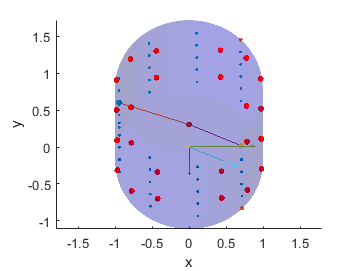




PointTable_A  = (PointTable2DT_A + repmat([P2D(1,1),P2D(1,2),0],size(PointTable2DT_A,1),1))*pinv(rot1);
PointTable_B  = (PointTable2DT_B + repmat([P2D(1,1),P2D(1,2),0],size(PointTable2DT_B,1),1))*pinv(rot1);



figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
% quiver3(0,0,0,5*x0,5*y0,5*z0)
scatter3(Point_out(1,:),Point_out(2,:),Point_out(3,:),5,"filled");
scatter3([P3(1),P4(1)],[P3(2),P4(2)],[P3(3),P4(3)],10,"filled");


quiver3(0,0,0,A(1),A(2),A(3))
quiver3(0,0,0,B(1),B(2),B(3))
quiver3(0,0,0,C(1),C(2),C(3))
quiver3(0,0,0,D(1),D(2),D(3))



scatter3(xN1,yN1,zN1,20,'filled')
scatter3(testP(1),testP(2),testP(3),20,'filled')
plot3([xN1,testP(1)],[yN1,testP(2)],[zN1,testP(3)])


scatter3(Tao2(1),Tao2(2),Tao2(3),20,'filled')
plot3([xN1,Tao2(1)],[yN1,Tao2(2)],[zN1,Tao2(3)])

scatter3(PointTable_A(:,1),PointTable_A(:,2),PointTable_A(:,3),20,'filled','red')
scatter3(PointTable_B(:,1),PointTable_B(:,2),PointTable_B(:,3),20,'filled','red')